# Goodput Calculation in LR-FHSS Networks

#### Based on "Asynchronous Contention Resolution-Aided ALOHA" (João Luiz Rebelatto)

## Variables

tf = 0.233472; % Fragment duration
th = 0.100; % Header duration
b = 10; % Payload length (in bytes)
CR = 1/3; % Coding rate
N = 3; % Headers replicates
C = 35; % Number of physical channels
l = 0.900; % Average interarrival
Devices_theo=[1000, 5000, 10000, 15000, 20000, 25000, 30000, 35000, 40000, 45000, 50000, 55000, ...
60000, 65000, 70000, 75000, 80000, 85000, 90000, 95000, 100000, 105000, 110000, 115000, 120000, ...
125000, 130000, 135000, 140000, 145000, 150000]; %Number of devices


## Equations

f = ceil((b+3)/(6*CR)) % Number of payload fragments

f = 7

gamma = ceil(f*CR) % Minimum required number of fragments

gamma = 3

lambda_h = 900; % Interarrivel between Headers
lambda_f = 900; % Interarrivel between Payload fragments

A_h = 2*lambda_h*th + lambda_f*(th + tf); % Vulnerable interval of the given copy of Header
A_f = 2*lambda_f*tf + lambda_h*(th + tf); % Vulnerable interval of the given copy of Payload Fragment

P_h = 1 - (1-(1 - 1/C).^(A_h-1)).^N; %Probability of receiving at least one header

P1 = (1 - 1/C).^(A_f - 1); % Probability of successfully receiving one payload fragment

%% binopdf(k, n, p) computes the binomial probability for k successes in n trials with success probability p

P_gamma = 1 - sum(binopdf(0:(gamma-1), f, P1)); % Probability of successfully receiving at least 'gamma' fragments


## Probability of successfully receiving at least 'gamma' fragments, and goodput

% Calcula probabilidade de sucesso do pacote
PacketSuccessProbability = P_gamma .* P_h;  % Certifique que P_H é compatível

% Calcula Goodput
Goodput = PacketSuccessProbability .* b .* (Devices_theo/8).* (1 ./ lambda_f);

% Opcional: exibe o resultado
disp('Goodput calculado:');

Goodput calculado:


disp(Goodput);

   1.0e-18 *

   -0.0009   -0.0043   -0.0086   -0.0129   -0.0172   -0.0215   -0.0258   -0.0301   -0.0344   -0.0387   -0.0430   -0.0473   -0.0516   -0.0559   -0.0602   -0.0645   -0.0688   -0.0731   -0.0774   -0.0817   -0.0860   -0.0903   -0.0946   -0.0989   -0.1032   -0.1075   -0.1118   -0.1161   -0.1204   -0.1247   -0.1290



**PLOT**

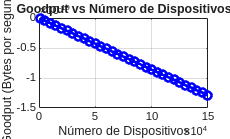

figure;
plot(Devices_theo, Goodput, 'b-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Número de Dispositivos');
ylabel('Goodput (Bytes por segundo)');
title('Goodput vs Número de Dispositivos');
grid on;